plot_type = "ReturnLoss";
save_plot = true;

input_file_path = "./2ND_ANTENNA.S2P";
title_str = "Receive Antenna";
out_nickname = "receive";


sparams  = sparameters(input_file_path);



if plot_type == "ReturnLoss"
    
    plt = rfplot(sparams,1,1)
    title(title_str + " S_{1,1} vs. Frequency")
    out_file_name = out_nickname + "_rl.png"
end

plt =   Line (dB(S_{11})) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×201 double]
              YData: [1×201 double]
              ZData: [1×0 double]

  Show all properties


out_file_name = "receive_rl.png"

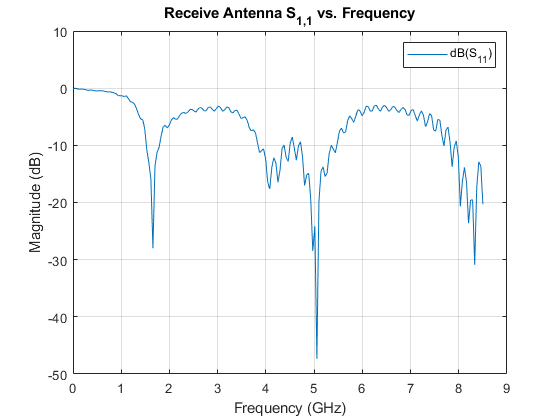



if save_plot
    saveas(gca,"../images/" + out_file_name);
end